Dati opzione

Rf=0

Rf = 0

sigma = 0.12

sigma = 0.1200

startPrice = 100

startPrice = 100

K = 100

K = 100

T = 200

T = 200

Delta = T/5 %lunghezza del passo

Delta = 40

year = 252

year = 252

t= Delta/year

t = 0.1587

u=exp(sigma*sqrt(t))

u = 1.0490

d=exp(-sigma*sqrt(t))

d = 0.9533

q=0.02

q = 0.0200

provo prima bls price

[call,put]=blsprice(100,K,0,200/252,sigma)

call = 4.2628

put = 4.2628

prezzo azioni con simulazione

ExpReturn = [Rf];
Sigmas = [sigma^2];
correlation=[sigma^2]

correlation = 0.0144

ExpCovariance = sigma^2

ExpCovariance = 0.0144

NumObs=200;
NumSim= 10000;
RetIntervals=1/252;
rng('default');  
RetExpected = portsim(ExpReturn, ExpCovariance, NumObs,RetIntervals, NumSim, 'Expected');
ExpSimulation=squeeze(RetExpected);

trovo i prezzi azionari

clear StockPrices
clear TickTimes
clear TickSeries
StockPrices= ret2tick(ExpSimulation,repmat(startPrice,1,NumSim))

StockPrices =   100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000  100.0000
   98.4100   99.8539   98.4447   99.7437   99.5580  100.1607   99.9851   99.3954   99.6733  100.9930  100.5690  101.2343  100.4587  100.1174   98.4582   98.8246  100.7820  100.7868  100.2940  100.6912   99.2361  100.4426   98.8205   99.8314   99.9489   99.2204   99.4566   99.2539  100.0194  100.6203  101.0030   98.9608  101.5400   99.1079  100.1502  100.3869   99.8931  100.2472  100.1831  100.5712  100.6132   98.9624  100.1626  101.0296  101.1136  100.6966  100.3445   99.9582  100

istogramma

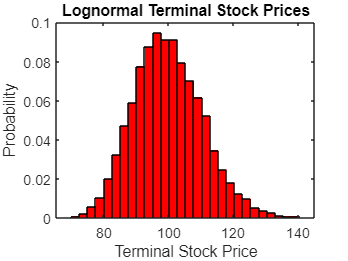

[count, BinCenter] = hist(StockPrices(end,:), 30);
figure(1)
bar(BinCenter, count/sum(count), 1, 'r')
xlabel('Terminal Stock Price')
ylabel('Probability')
title('Lognormal Terminal Stock Prices')

grafico

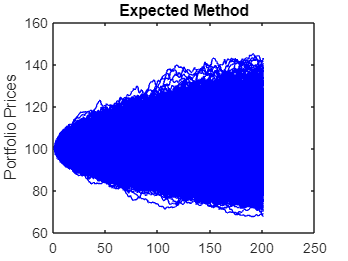

plot(StockPrices, '-b')
ylabel('Portfolio Prices')
title('Expected Method')

pricing call

term=StockPrices(201,:)';
payoff=(term-100);
payoff(payoff < 0) = 0

payoff =     2.8342
         0
   12.8848
         0
    4.3395
         0
    7.6666
         0
    0.1762
   12.2221


callmontecarlo=mean(payoff)/(1+Rf)

callmontecarlo = 4.2757

pricing put

payoff1=(100-term);
payoff1(payoff1 < 0) = 0

payoff1 =          0
    0.1443
         0
   13.8381
         0
   17.5729
         0
   18.2298
         0
         0


putmontecarlo=mean(payoff1)/(1+Rf)

putmontecarlo = 4.2680